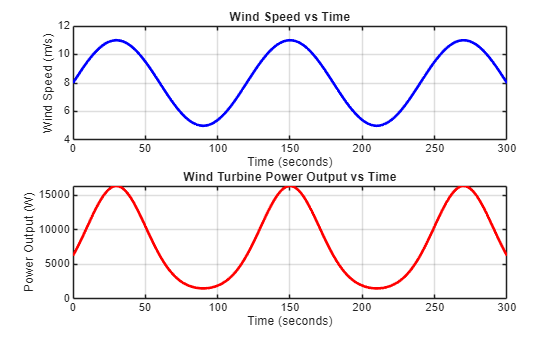

% Author: Christopher Bourjaili
% Module 2
% Project 11
% Title: Wind Turbine Power Output
%
% Summary of Code:
% - Simulates wind speed changing over time using a sinusoidal model.
% - Uses a simplified turbine power equation based on wind speed.
% - Calculates instantaneous turbine power output each time step.
% - Determines average power over the full simulation.
% - Creates wind speed vs time and power vs time plots.
% - Demonstrates how wind variability affects energy production.
%
% What I Learned:
% This project demonstrated how MATLAB can simulate renewable energy
% systems using time-varying inputs, equations, and plotting tools.
% I learned that turbine power depends strongly on wind speed, so even
% small wind increases can greatly raise output. I also practiced using
% average values to evaluate overall system performance under changing
% environmental conditions.

clc
clear
close all

dt = 1;                    
t_total = 300;             

t = 0:dt:t_total;
n = length(t);

rho = 1.225;              
A = 50;                   
Cp = 0.40;                

wind_speed = zeros(1,n);
power = zeros(1,n);

for i = 1:n

    wind_speed(i) = 8 + 3*sin(2*pi*t(i)/120);

    if wind_speed(i) < 0
        wind_speed(i) = 0;
    end
    
    power(i) = 0.5 * rho * A * Cp * wind_speed(i)^3;
    
end

avg_power = mean(power);

figure

subplot(2,1,1)
plot(t, wind_speed,'b','LineWidth',2)
grid on
xlabel('Time (seconds)')
ylabel('Wind Speed (m/s)')
title('Wind Speed vs Time')

subplot(2,1,2)
plot(t, power,'r','LineWidth',2)
grid on
xlabel('Time (seconds)')
ylabel('Power Output (W)')
title('Wind Turbine Power Output vs Time')


fprintf('Average Power Output = %.2f W\n', avg_power);

Average Power Output = 8513.79 W



disp('Discussion:')

Discussion:


disp('1. Power output rises rapidly as wind speed increases.')

1. Power output rises rapidly as wind speed increases.


disp('2. Because power depends on wind speed cubed, small wind changes matter.')

2. Because power depends on wind speed cubed, small wind changes matter.


disp('3. Variable wind creates fluctuating energy production.')

3. Variable wind creates fluctuating energy production.


disp('4. Average output is useful for estimating long-term performance.')

4. Average output is useful for estimating long-term performance.
